# Building Management System Requirement Analysis

Copyright 2024 - 2025 The MathWorks, Inc.

This Live Script contains the steps to read building data, parameterize the model, and run the simulation. You will learn how to calculate energy requirements for maintaining the building at a set point temperature. In this example, the **Control** subsystem provides energy to the **Building** custom component through the port **S** to maintain the building temperature at a desired setpoint value. No heat pump, room radiator, or underfloor heating or cooling are modelled. Based on the solar load and changes in ambient temperature, the energy required to keep building at the setpoint temperature is calculated. The model is run at fixed hourly-timestep.

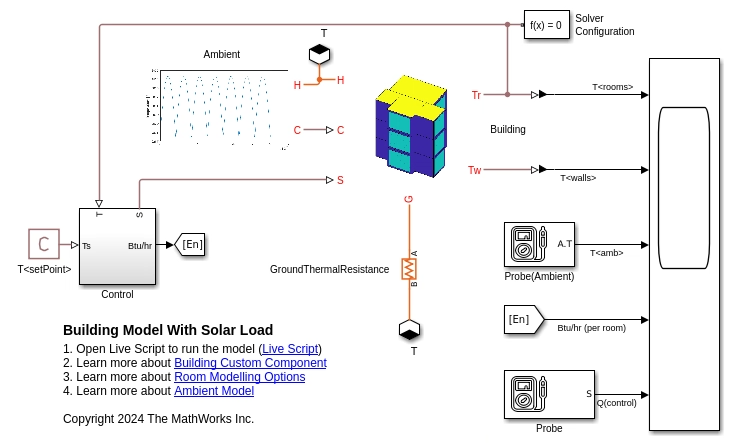

## Read Building Data

Load the building data with solar load from the XML file.

[apartment3D, geoLocation, dateTimeVec] = ...
    readBuildingDataXML(FileName="building_with_solar_load.xml");

    {'Location:Vienna'}

Simulation Duration:
*** Start Time :01-Jan-2024 01:00:00
*** End Time   :08-Jan-2024 01:00:00
*** Room Names in Building : FireExit,Bathroom,Kitchen,Bedroom,LivingRoom



nDays = days(dateTimeVec(1,end)-dateTimeVec(1,1));

Set viewing direction for all 3D plots.

viewingAngle = [-1 -1 1]; 

Create an icon for the building custom model in Simscape.

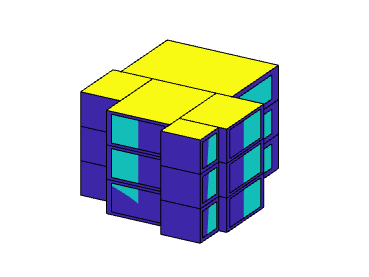

createIconBuildingCustomComponent(Building=apartment3D,...
                                  PlotViewDirection=viewingAngle);

## Parameterize Model

The function `initializeBuildingSimulationParameters` initializes the parameter required by the model and returns them in data struct `physTable` and `opsParams`. You must specify the average day-time temperatures `DayTemperature`, average night-time temperatures `NightTemperature`, and the percentage variation of temperature from the average (`DayTemperatureVar` and `NightTemperatureVar`). You must provide these average temperatures for all days, `nDays`, as included in the building data XML part file. The building desired set point temperature is specified by the name value pair `RoomTsetPoint`.

[physTable,opsParams] = initializeBuildingSimulationParameters(...
                        Building=apartment3D,...
                        DateTimeVec=dateTimeVec,...
                        Location=geoLocation,...
                        GroundResistance=simscape.Value(100,"K/W"),...
                        RoomTsetPoint=simscape.Value(293,"K"),...
                        DayTemperature=simscape.Value(275*ones(1,nDays),"K"),...
                        DayTemperatureVar=0.1,...
                        NightTemperature=simscape.Value(271*ones(1,nDays),"K"),...
                        NightTemperatureVar=0.1);

Create data struct to define the components and the building thermal network needed for the simulation.

bldgThermalNetwork = getParamsForSimscapeComponent(Building=apartment3D,...
                                                   PhysicsTableData=physTable,...
                                                   OperationalData=opsParams);

Specify building material properties. You must use name value pairs in the function below to edit any wall or window material property.

buildingMaterial = initializeBuildingMaterialProperties(DisplayData=true,...
                                                        ExternalWallThickness=simscape.Value(0.35,"m"),...
                                                        ExternalWallAbsorptivity=simscape.Value(0.3,"1"),...
                                                        RoofThickness=simscape.Value(0.35,"m"),...
                                                        RoofAbsorptivity=simscape.Value(0.3,"1"));

*** You must not specify values marked as NaN in the table.
*** Block default values are provided where name-value-pair are not defined.
                                    Roof    Floor    ExternalWall    InternalWall    Window
                                    ____    _____    ____________    ____________    ______

    Absorptivity [-]                 0.3     NaN          0.3             NaN          0.4 
    Transmissivity [-]               NaN     NaN          NaN             NaN          0.2 
    Thickness [m]                   0.35     0.3         0.35             0.3         0.01 
    Density [kg/m^3]                2400    2400         2400            2400         4000 
    Heat Capacity [J/kg-K]           750     750       

Specify the room modelling option. For requriement analysis, specify the name value pair of `RoomModel` as `Thermal Requirements`. For more information on the `Thermal Management: Radiator Model`, or `Thermal Management: Under Floor Model`, or `Thermal Management: Radiator and Under Floor Model`, options, see [Simulate Building Energy Management System](matlab:open('./SimulateBuildingEnergyManagement.mlx')).

mdl = setParametersForBuildingCustomComponent(Building=apartment3D,...
                                              BuildingNetworkData=bldgThermalNetwork,...
                                              RoomModel="Thermal Requirements",...
                                              Duration=dateTimeVec,...
                                              ExternalHTC=simscape.Value(5,"W/(K*m^2)"),...
                                              InternalHTC=simscape.Value(5,"W/(K*m^2)"),...
                                              BuildingMaterial=buildingMaterial);

Parameterized Model :BuildingModelWithSolarLoad.slx
*** Simulation Time = 168-hours
*** Model Parameterized for Time =169-hours
*** Solver :Fixed-step (ode1be)


## Run Simulation

Open the model. Run the model and analyse the results. The model may take time to run based on the building size and model parameterization features.

open_system(mdl);
% % Uncomment below to run the analysis in Live Script
% bldgSimRes = sim(mdl);

To run the model, enter the following commands at the MATLAB Command Prompt:

## Plot Simulation Results

Plot pre-generated results data if the simulation is not run. To run the simulation, follow the steps outlined in Run Simulation.

% Load pre-generated data saved in a MAT file.
if ~exist('bldgSimRes','var')
    load("reqAnalysisResults.mat");
end

Plot the room, wall, and ambient temperature variation.

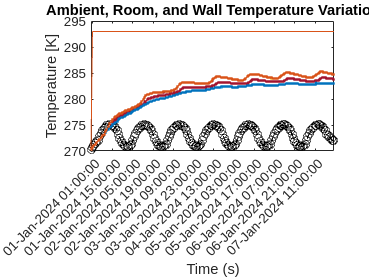

if exist('bldgSimRes','var')
    plotTimeSeriesTempRoomWallAmbient(SimlogData=bldgSimRes,...
                                      Duration=dateTimeVec,...
                                      PlotXAxisParts=12); 
end

Plot the heating and cooling requirement analysis summary.

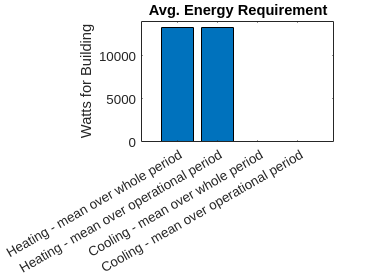

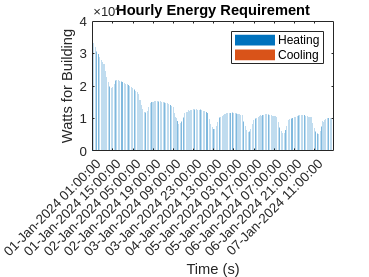

if exist('bldgSimRes','var')
    plotHeatCoolingRequirementAnalysisOutput(SimlogData=bldgSimRes,...
                                             Duration=dateTimeVec,...
                                             PlotXAxisParts=12,...
                                             EnergyEntireBuilding=true,...
                                             PlotUnit="Watts");
end

The mean value of cooling and heating requirement is a good indication of the heat pump capacity required for actual operation.

showPlotForBuildingT = false;

You can also plot solar data by setting the above drop down to `Display Plot`.

if showPlotForBuildingT && exist('bldgSimRes','var')
    buildingDataWithTemp = getBuildingRoomTemperatureData(Building=apartment3D,...
                                                          SimlogData=bldgSimRes);
    count = 1;
    for nHrs = 1:length(dateTimeVec)
        figure(count)
        plot3DlayoutBuilding(Building=buildingDataWithTemp,...
                             PlotViewDirection=viewingAngle,...
                             ColorScheme="temperature",...
                             Hour=nHrs);
        title(strcat(geoLocation.Row,', Date/Time :',string(dateTimeVec(1,nHrs))));
        count = count + 1;
    end
end